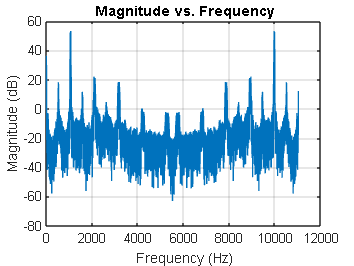

%Q1
% Load the .wav file using audioread
filename = 'flute1.wav';
[audio, sampleRate] = audioread(filename);

% Perform FFT on the audio data
n = length(audio); % Length of the audio data
frequencies = (0:n-1)*(sampleRate/n); % Frequency values corresponding to FFT bins
audio_fft = fft(audio); % Compute FFT

% Calculate the magnitude of the FFT and convert to dB scale
magnitude = 20*log10(abs(audio_fft));

% Plot the magnitude versus frequency
plot(frequencies, magnitude);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Magnitude vs. Frequency');
grid on;


% Find the index of the peak magnitude in the DFT
[~, peakIndex] = max(abs(audio_fft));

% Calculate the corresponding frequency value (in Hz)
fundamental_frequency = frequencies(peakIndex);

disp(['Fundamental Frequency: ', num2str(fundamental_frequency), ' Hz']);

Fundamental Frequency: 1063.2 Hz


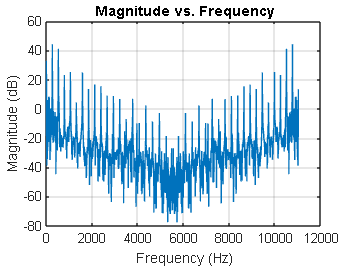

% Load the .wav file using audioread
filename = 'piano1.wav';
[audio, sampleRate] = audioread(filename);

% Perform FFT on the audio data
n = length(audio); % Length of the audio data
frequencies = (0:n-1)*(sampleRate/n); % Frequency values corresponding to FFT bins
audio_fft = fft(audio); % Compute FFT

% Calculate the magnitude of the FFT and convert to dB scale
magnitude = 20*log10(abs(audio_fft));

% Plot the magnitude versus frequency
plot(frequencies, magnitude);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Magnitude vs. Frequency');
grid on;

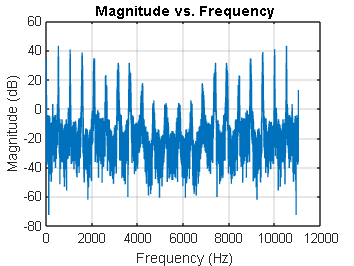

% Load the .wav file using audioread
filename = 'violin1.wav';
[audio, sampleRate] = audioread(filename);

% Perform FFT on the audio data
n = length(audio); % Length of the audio data
frequencies = (0:n-1)*(sampleRate/n); % Frequency values corresponding to FFT bins
audio_fft = fft(audio); % Compute FFT

% Calculate the magnitude of the FFT and convert to dB scale
magnitude = 20*log10(abs(audio_fft));

% Plot the magnitude versus frequency
plot(frequencies, magnitude);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Magnitude vs. Frequency');
grid on;


% Find the index of the peak magnitude in the DFT
[~, peakIndex] = max(abs(audio_fft));

% Calculate the corresponding frequency value (in Hz)
fundamental_frequency = frequencies(peakIndex);
disp(['Fundamental Frequency: ', num2str(fundamental_frequency), ' Hz']);

Fundamental Frequency: 522.6397 Hz


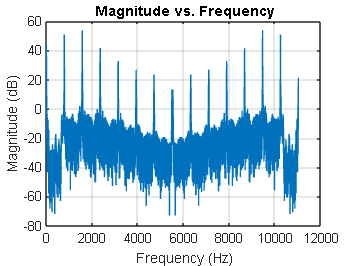

% Load the .wav file using audioread
filename = 'trumpet1.wav';
[audio, sampleRate] = audioread(filename);

% Perform FFT on the audio data
n = length(audio); % Length of the audio data
frequencies = (0:n-1)*(sampleRate/n); % Frequency values corresponding to FFT bins
audio_fft = fft(audio); % Compute FFT

% Calculate the magnitude of the FFT and convert to dB scale
magnitude = 20*log10(abs(audio_fft));

% Plot the magnitude versus frequency
plot(frequencies, magnitude);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Magnitude vs. Frequency');
grid on;


% Find the index of the peak magnitude in the DFT
[~, peakIndex] = max(abs(audio_fft));

% Calculate the corresponding frequency value (in Hz)
fundamental_frequency = frequencies(peakIndex);

disp(['Fundamental Frequency: ', num2str(fundamental_frequency), ' Hz']);

Fundamental Frequency: 1566.2431 Hz





% Find the index of the peak magnitude in the DFT
[~, peakIndex] = max(abs(audio_fft));

% Calculate the corresponding frequency value (in Hz)
fundamental_frequency = frequencies(peakIndex)

fundamental_frequency = 1.5662e+03


disp(['Fundamental Frequency: ', num2str(fundamental_frequency), ' Hz']);

Fundamental Frequency: 1566.2431 Hz


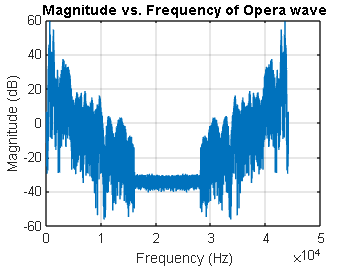

% Step 1: Read the audio file
audioFilePath = 'Recording (2).m4a';  % Replace with the path to your audio file
[y, fs] = audioread(audioFilePath);

% Step 2: Compute the FFT of the audio signal
N = length(y);  % Length of the audio signal
Y = fft(y);     % Compute the FFT

% Step 3: Find the fundamental frequency
frequencies = (0:N-1)*(fs/N);  % Frequency axis
magnitude = 20*log10(abs(Y));            % Magnitude of FFT
[~, idx] = max(magnitude(1:N/2+1));  % Find the index of the maximum magnitude
fundamentalFrequency = frequencies(idx);  % Fundamental frequency in Hz

% Display the results
fprintf('Fundamental Frequency: %.2f Hz\n', fundamentalFrequency);
figure;
% You can also plot the FFT if desired
plot(frequencies, magnitude);
title('FFT of Reference Audio Signal ');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

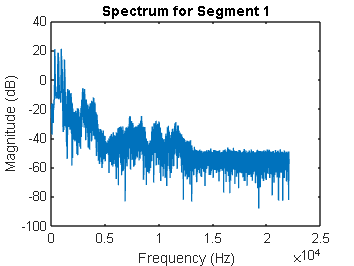

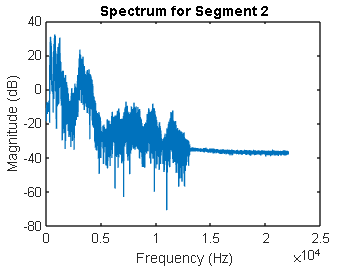

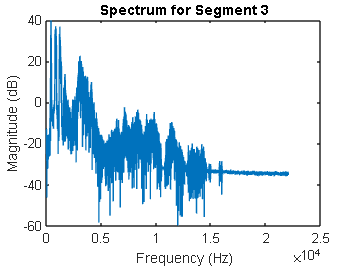

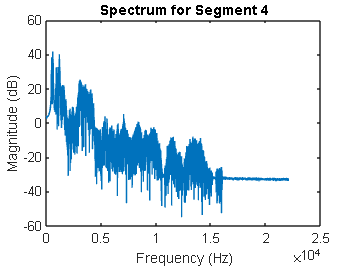

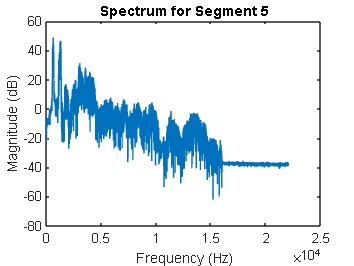

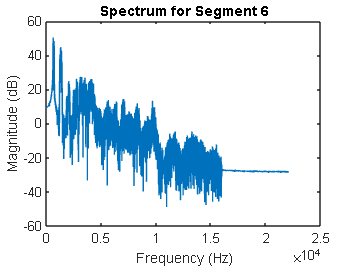

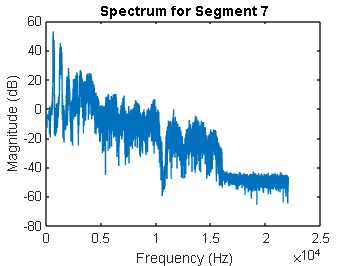

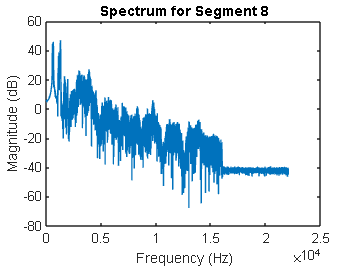

%%
% Step 1: Read the audio file
audioFilePath = 'Recording (3).m4a';  % Replace with the path to your audio file
[y, fs] = audioread(audioFilePath);

% Step 2: Compute the FFT of the audio signal
N = length(y);  % Length of the audio signal
Y = fft(y);     % Compute the FFT

% Step 3: Find the fundamental frequency
frequencies = (0:N-1)*(fs/N);  % Frequency axis
magnitude = 20*log10(abs(Y));            % Magnitude of FFT
[~, idx] = max(magnitude(1:N/2+1));  % Find the index of the maximum magnitude
fundamentalFrequency1 = frequencies(idx);  % Fundamental frequency in Hz
fprintf('Fundamental Frequency: %.2f Hz\n', fundamentalFrequency1);
% Display the results
figure;
% You can also plot the FFT if desired
plot(frequencies, magnitude);
title('FFT of Audio Signal Recording (3).m4a');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
%%
if((fundamentalFrequency1> 1260.593) && (fundamentalFrequency1<1393.287))
    fprintf('ACCESS GRANTED');
else
    fprintf('ACCESS DENIED');
end
%%

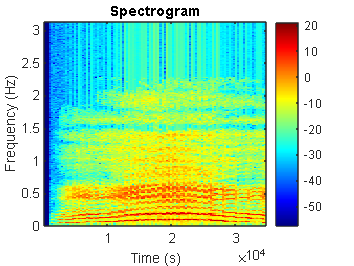

% Step 1: Read the audio file
audioFilePath = 'Silent.m4a';  % Replace with the path to your audio file
[y, fs] = audioread(audioFilePath);

% Step 2: Compute the FFT of the audio signal
N = length(y);  % Length of the audio signal
Y = fft(y);     % Compute the FFT

% Step 3: Find the fundamental frequency
frequencies = (0:N-1)*(fs/N);  % Frequency axis
magnitude = 20*log10(abs(Y));            % Magnitude of FFT
[~, idx] = max(magnitude(1:N/2+1));  % Find the index of the maximum magnitude
fundamentalFrequency2 = frequencies(idx);  % Fundamental frequency in Hz

% Display the results

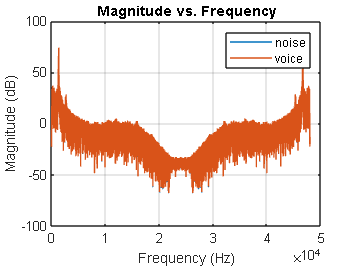

fundamental_frequency = 1.0e+03 *

    1.3464    1.3464


fprintf('Fundamental Frequency: %.2f Hz\n', fundamentalFrequency2);
figure;

% You can also plot the FFT if desired
plot(frequencies, magnitude);
title('FFT of Audio Signal Silent.m4a');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
%%
if((fundamentalFrequency2> 1391.047) && (fundamentalFrequency2<1537.473))
    fprintf('ACCESS GRANTED');
else
    fprintf('ACCESS DENIED');
end

%Q.3
% Load the .wav file using audioread
filename = 'Opera.wav';
[audio, sampleRate] = audioread(filename);

% Perform FFT on the audio data
n = length(audio); % Length of the audio data
frequencies = (0:n-1)*(sampleRate/n) ;% Frequency values corresponding to FFT bins
audio_fft = fft(audio); % Compute FFT

% Calculate the magnitude of the FFT and convert to dB scale
magnitude = 20*log10(abs(audio_fft));

% Plot the magnitude versus frequency
plot(frequencies, magnitude);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Magnitude vs. Frequency of Opera wave');
grid on;

% Find the index of the peak magnitude in the DFT
[~, peakIndex] = max(abs(audio_fft));

[x, fs] = audioread('Opera.wav');

segment_length = 22000;
signal_length = length(x);
num_segments = floor(signal_length / segment_length);

for i = 1:num_segments
    start_idx = (i - 1) * segment_length + 1;
    end_idx = i * segment_length;
    segment = x(start_idx:end_idx);

    % Compute the spectrum using FFT
    spectrum = fft(segment);
    spectrum = abs(spectrum(1:segment_length/2+1)); % Take only positive frequencies
    
    % Frequency axis
    f = (0:(segment_length/2)) * (fs / segment_length);

    % Plot the spectrum
    figure;
    plot(f, 20*log10(spectrum)); % Convert to dB scale for better visualization
    xlabel('Frequency (Hz)');
    ylabel('Magnitude (dB)');
    title(['Spectrum for Segment ', num2str(i)]);
end

% Load the .wav file using audioread
filename = 'Opera.wav';
[audio, sampleRate] = audioread(filename);


window_size = 4096;          % Size of the analysis window
overlap = 2048;             % Overlap between consecutive windows
[S, f, t] = spectrogram(audio, hamming(window_size), overlap);
imagesc(t, f, 10*log10(abs(S))); % Plot in dB
axis xy;
colormap jet;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram');
colorbar;